# **MATLAB Onramp: project**

## **Stellar Motion**

load starData.mat
nObs = size(spectra,1)

nObs = 357

lambdaStart = 630.02 % starting wavelength (λstart)

lambdaStart = 630.0200

lambdaDelta = 0.14 % spacing

lambdaDelta = 0.1400

lambdaEnd = lambdaStart+(nObs-1).*lambda_delta % ending wavelength (λstart)

lambdaEnd = 679.8600

lambda = lambdaStart:lambdaDelta:lambdaEnd % wavelengths in the spectrum

lambda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800


s = spectra(:,6) % default: 6th column is the spectrum of star HD 94028

s = 1.0e-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


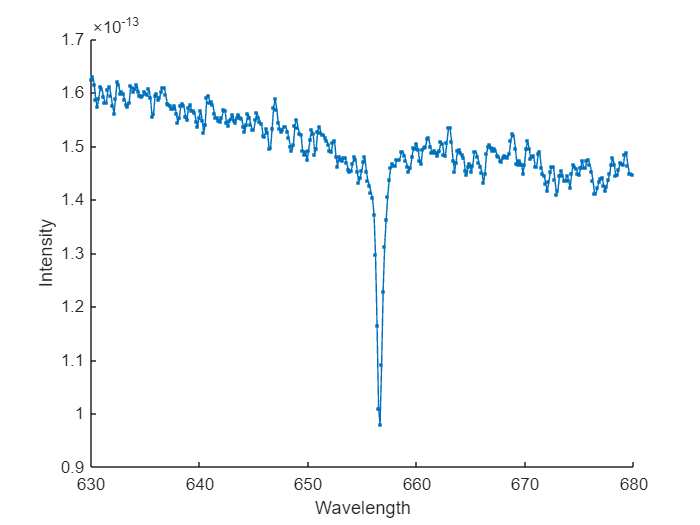

hold on
plot(lambda,s,".-")
xlabel("Wavelength")
ylabel("Intensity")

[sHa,idx] = min(s) % idx: location of the hydrogen-alpha line (λHa)

sHa = 9.8010e-14

idx = 191

lambdaHa = lambda(idx)

lambdaHa = 656.6200

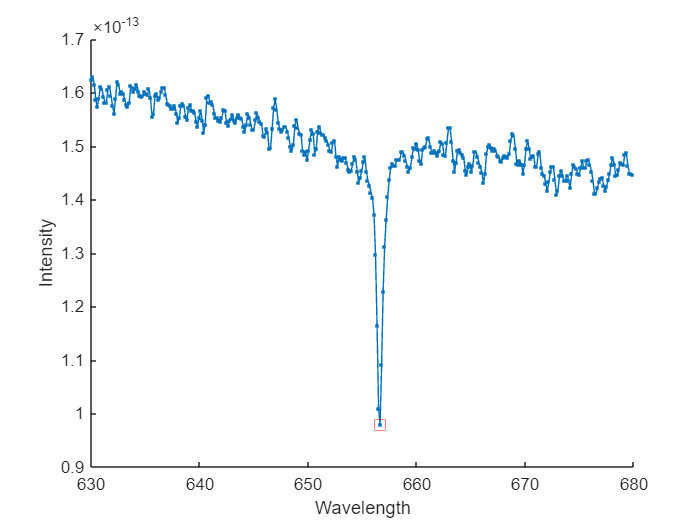

plot(lambdaHa,sHa,"rs",MarkerSize=8)

z = (lambdaHa/656.28)-1 % 656.28: wavelength of the hydrogen-alpha line of HD 94028

z = 5.1807e-04

speed1 = z*299792.458 % 299792.458: speed of light

speed1 = 155.3139

Now that the Redshift is found, the script can be modified to repeat the calculation on any star in the spectra matrix by changing the slider in line 7.

## **Compare Stellar Spectra**

[sHa,idx] = min(spectra);
lambdaHa = lambda(idx);
z = (lambdaHa/656.28)-1;
speed = z*299792.458

speed =   -36.5445 -100.4973  -36.5445   27.4083   27.4083  155.3139 -228.4029


% a positive speed means that the star is moving away from Earth(redshifted spectrum).
% a negative speed means that the star is moving toward Earth(blueshifted spectrum).

for v=1:7
    s = spectra(:,v)

    if speed(v)<=0
        plot(lambda,s,"--")

    hold on

    else
        if speed(v)>0
            plot(lambda,s,LineWidth=3)
        end

    end

end

s = 1.0e-12 *

    0.3088
    0.3136
    0.3105
    0.3076
    0.3088
    0.3105
    0.3122
    0.3101
    0.3078
    0.3047


s = 1.0e-12 *

    0.1340
    0.1338
    0.1347
    0.1357
    0.1354
    0.1343
    0.1335
    0.1325
    0.1335
    0.1329


s = 1.0e-13 *

    0.5981
    0.6074
    0.6176
    0.6252
    0.6271
    0.6221
    0.6192
    0.6200
    0.6261
    0.6249


s = 1.0e-13 *

    0.8919
    0.8981
    0.9152
    0.9311
    0.9355
    0.9321
    0.9286
    0.9247
    0.9240
    0.9177


s = 1.0e-12 *

    0.1088
    0.1084
    0.1104
    0.1124
    0.1122
    0.1136
    0.1138
    0.1130
    0.1124
    0.1108


s = 1.0e-12 *

    0.1625
    0.1630
    0.1615
    0.1586
    0.1574
    0.1589
    0.1611
    0.1607
    0.1593
    0.1582


s = 1.0e-13 *

    0.3918
    0.3821
    0.3712
    0.3776
    0.3910
    0.3955
    0.4023
    0.3986
    0.3874
    0.3793


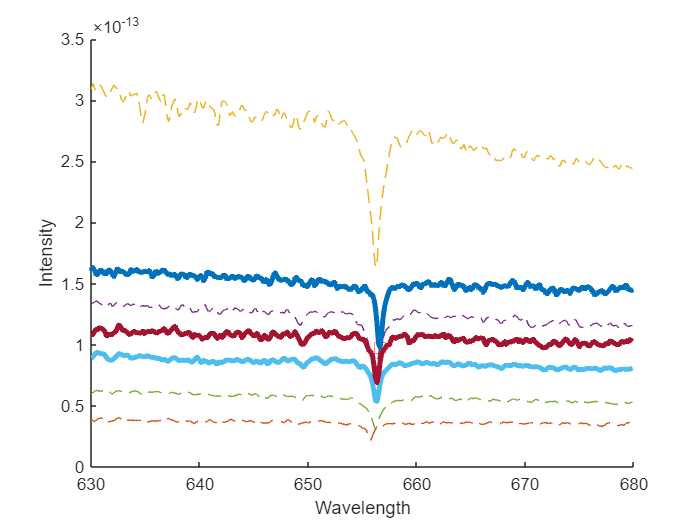


hold off

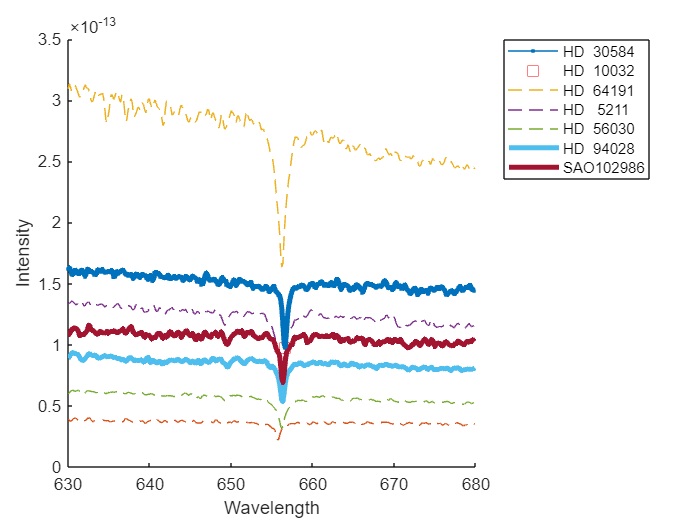

legend(starnames,"location","northeastoutside")

movaway = starnames(speed>0)

movaway = 3×1 string array
    "HD   5211"
    "HD  56030"
    "HD  94028"


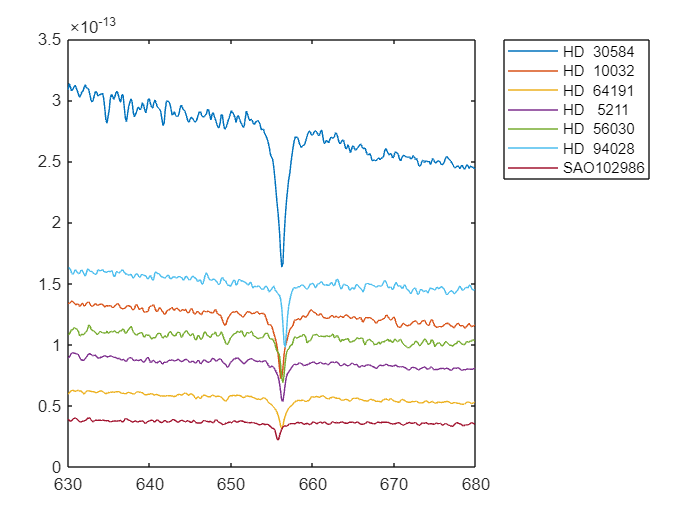

% general overview
plot(lambda,spectra)
legend(starnames,"location","northeastoutside")